# m0514 Script for Plotting Roll Dynamics Estimation

## Load Matfiles if replotting results

% load('C:\Users\jason\Cranfield University\2021-AM-GDP-Team1-UGT-SATM - General\Report and Poster\05_SE\CorneringBank_Test\CorneringBank_Test.mat')

## Find the means and ranges of the actual quantities

legend_fontsize = 16;
title_fontsize = 16;

mean_CM_BodyRoll_rad = mean(CM_BodyRoll_rad);

mean_CM_BodyRollVel_radps = mean(CM_BodyRollVel_radps);

mean_CM_RoadBank_rad = mean(CM_RoadBank_rad);

range_CM_BodyRoll_rad = max(CM_BodyRoll_rad) - min(CM_BodyRoll_rad)

range_CM_BodyRoll_rad = 0.0450


range_CM_BodyRollVel_radps = max(CM_BodyRollVel_radps) - min(CM_BodyRollVel_radps)

range_CM_BodyRollVel_radps = 0.1756


range_CM_RoadBank_rad = max(CM_RoadBank_rad) - min(CM_RoadBank_rad)

range_CM_RoadBank_rad = 0

## Find Root Mean Square Errors for Roll Angle Estimates

error_Est_BodyRoll_CF_rad = CM_BodyRoll_rad - Est_BodyRoll_CF_rad;

RMSE_Est_BodyRoll_CF_rad = rms(error_Est_BodyRoll_CF_rad);

NRMSE_Est_BodyRoll_CF_rad = RMSE_Est_BodyRoll_CF_rad/range_CM_BodyRoll_rad

NRMSE_Est_BodyRoll_CF_rad = 0.0225


error_Est_BodyRoll_Fr2q0_rad = CM_BodyRoll_rad - Est_BodyRoll_Fr2q0_rad;

RMSE_Est_BodyRoll_Fr2q0_rad = rms(error_Est_BodyRoll_Fr2q0_rad);

NRMSE_Est_BodyRoll_Fr2q0_rad = RMSE_Est_BodyRoll_Fr2q0_rad/range_CM_BodyRoll_rad

NRMSE_Est_BodyRoll_Fr2q0_rad = 0.0583

## Find Root Mean Square Errors for Roll Velocity Estimates

error_Est_BodyRollVel_CF_radps = CM_BodyRollVel_radps - Est_BodyRollVel_CF_radps;

RMSE_Est_BodyRollVel_CF_radps = rms(error_Est_BodyRollVel_CF_radps);

NRMSE_Est_BodyRollVel_CF_radps = RMSE_Est_BodyRollVel_CF_radps/range_CM_BodyRollVel_radps

NRMSE_Est_BodyRollVel_CF_radps = 0.0576


% error_Est_BodyRollVel_Fr2q0_radps = CM_BodyRollVel_radps - Est_BodyRollVel_Fr2q0_radps;
% 
% RMSE_Est_BodyRollVel_Fr2q0_radps = rms(error_Est_BodyRollVel_Fr2q0_radps)
% 
% NRMSE_Est_BodyRollVel_Fr2q0_radps = RMSE_Est_BodyRollVel_Fr2q0_radps/range_CM_BodyRollVel_radps


## Find Root Mean Square Errors for Bank Angle Estimates

error_Est_RoadBank_rad = CM_RoadBank_rad - Est_RoadBank_rad;

RMSE_Est_RoadBank_rad = rms(error_Est_RoadBank_rad);
RMSE_Est_RoadBank_deg = RMSE_Est_RoadBank_rad*180/pi

RMSE_Est_RoadBank_deg = 2.9632


NRMSE_Est_RoadBank_rad = RMSE_Est_RoadBank_rad/range_CM_RoadBank_rad

NRMSE_Est_RoadBank_rad = Inf

## Convert radians to degrees

CM_BodyRollVel_degps = CM_BodyRollVel_radps*180/pi;
Est_BodyRollVel_CF_degps = Est_BodyRollVel_CF_radps*180/pi;

CM_Roll_deg = CM_Roll_rad*180/pi;
CM_RollVel_degps = CM_RollVel_radps*180/pi;

CM_BodyRoll_deg = CM_BodyRoll_rad*180/pi;
Est_BodyRoll_Fr2q0_deg = Est_BodyRoll_Fr2q0_rad*180/pi;
Est_BodyRoll_CF_deg = Est_BodyRoll_CF_rad*180/pi;

CM_RoadBank_deg = CM_RoadBank_rad*180/pi;
Est_RoadBank_deg = Est_RoadBank_rad*180/pi;

CM_SideSlipAngle_deg = CM_SideSlipAngle_rad*180/pi;

## Plot Roll Dynamics

%define x and y axis limits
xl = [0 Time(end)]

xl =          0   20.0020


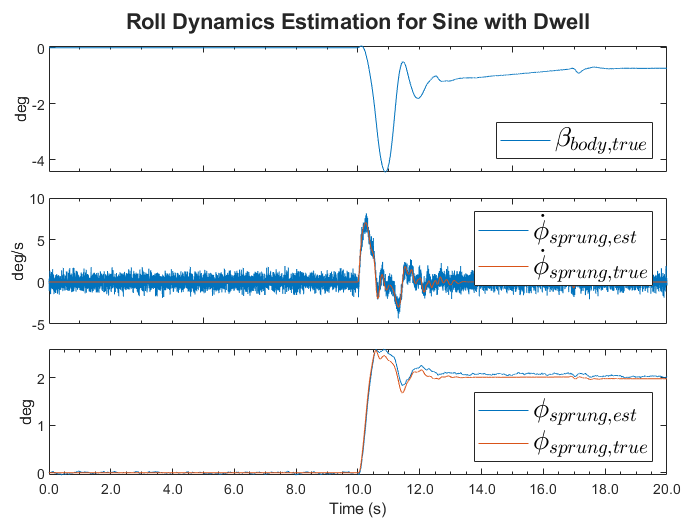

% xl = [9.5 13] %For Step Steer 
% xl = [14.5 30.5] %For Sine With Dwell 
% xl = [26.5 32.5] %For banked corner 

figure(1)
clf
t1 = tiledlayout(3,1);


ax1a = nexttile;

plot(Time,CM_SideSlipAngle_deg)
legend ("$\beta_{body,true}$",...
    'Interpreter','latex','FontSize',legend_fontsize,'location','southeast')
ylabel('deg')

ax1b = nexttile;
plot(Time,Est_BodyRollVel_CF_degps,Time,CM_BodyRollVel_degps)
legend ('$\dot{\phi}_{sprung,est}$',"$\dot{\phi}_{sprung,true}$", ...
    'Interpreter','latex','FontSize',legend_fontsize,'location','northeast')
ylabel('deg/s')

ax1c = nexttile;
plot(Time,Est_BodyRoll_CF_deg,...
    Time,CM_BodyRoll_deg);
legend ("$\phi_{sprung,est}$","$\phi_{sprung,true}$",'Interpreter','latex', ...
    'FontSize',legend_fontsize,'location','southeast')
%    "Ride Height Estimated Sprung Body Roll Angle (deg)", ...  
ylabel('deg')


%Combine the subplots
linkaxes([ax1a,ax1b,ax1c],'x')
%
%  title(t1, {'Roll Dynamics Estimation for Step Steer,' '400 deg steering wheel angle, 100 km/h'})
title(t1, 'Roll Dynamics Estimation for Sine with Dwell')
% title(t1, 'Roll Dynamics Estimation for 50m radius, 90 degree left turn, 23.58 degree inward banked corner')
t1.Title.FontWeight = 'bold';
xlabel('Time (s)');
% xticks(xl(1):1:xl(2))
set([ax1a ax1b ax1c],'XMinorTick','on')
xtickformat('%.1f')
xticklabels([ax1a ax1b],{})

t1.Padding = 'compact';
t1.TileSpacing = 'compact';

xlim(xl) 

## Plot Roll Dynamics for Banked Corner

%define x and y axis limits
xl = [0 14] %For banked corner 

xl =      0    14


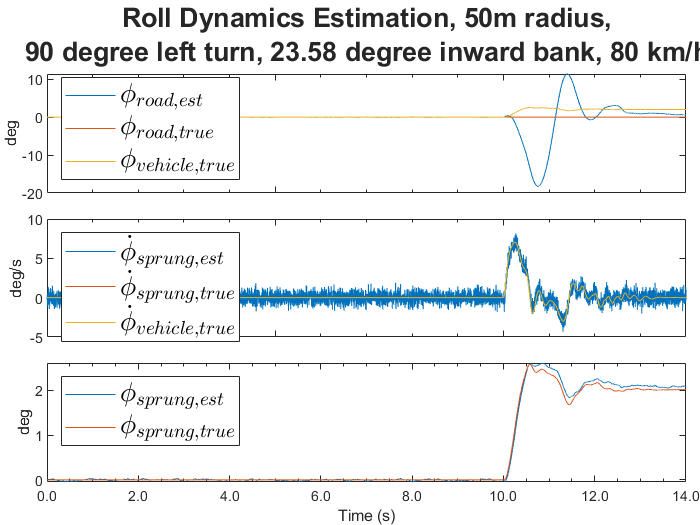

figure(3)
clf
t3 = tiledlayout(3,1);


ax3a = nexttile;

plot(Time,Est_RoadBank_deg,Time,CM_RoadBank_deg,Time,CM_Roll_deg)
legend ("$\phi_{road,est}$","$\phi_{road,true}$","$\phi_{vehicle,true}$", ...
    'Interpreter','latex','FontSize',legend_fontsize,'location','southwest')
ylabel('deg')

ax3b = nexttile;
plot(Time,Est_BodyRollVel_CF_degps,Time,CM_BodyRollVel_degps,Time,CM_RollVel_degps)
legend ('$\dot{\phi}_{sprung,est}$',"$\dot{\phi}_{sprung,true}$", ...
    "$\dot{\phi}_{vehicle,true}$",'Interpreter','latex','FontSize',legend_fontsize,'location','northwest')
ylabel('deg/s')

ax3c = nexttile;
plot(Time,Est_BodyRoll_CF_deg,...
    Time,CM_BodyRoll_deg);
legend ("$\phi_{sprung,est}$","$\phi_{sprung,true}$",'Interpreter','latex', ...
    'FontSize',legend_fontsize,'location','northwest')
%    "Ride Height Estimated Sprung Body Roll Angle (deg)", ...  
ylabel('deg')

%Combine the subplots
linkaxes([ax3a,ax3b,ax3c],'x')
% 
title(t3, {'Roll Dynamics Estimation, 50m radius,','90 degree left turn, 23.58 degree inward bank, 80 km/h'})
%title(t3, 'Roll Dynamics Estimation for Sine with Dwell')
t3.Title.FontWeight = 'bold';
t3.Title.FontSize = title_fontsize;
xlabel('Time (s)');
% xticks(xl(1):1:xl(2))
set([ax3a ax3b ax3c],'XMinorTick','on')
xtickformat('%.1f')
xticklabels([ax3a ax3b],{})

t3.Padding = 'none';
t3.TileSpacing = 'compact';

xlim(xl) 

## Save Result (filename for each testrun)

%% Cornering at Banked Angle

% rawfilename=('C:\Users\jason\Cranfield University\2021-AM-GDP-Team1-UGT-SATM - General\Report and Poster\05_SE\CorneringBank_Test\CorneringBank_Test.mat');
% save(rawfilename,'Time','CM_BodyRoll_rad', 'CM_BodyRollVel_radps', 'CM_RoadBank_rad', ...
%     'Est_BodyRollVel_CF_radps','Est_BodyRoll_CF_rad', ...
%     'Est_BodyRoll_Fr2q0_rad','Est_BodyRoll_Fr2q0_rad', 'Est_RoadBank_rad')
% 
% NRMEfilename=('C:\Users\jason\Cranfield University\2021-AM-GDP-Team1-UGT-SATM - General\Report and Poster\05_SE\CorneringBank_Test\NRMSE.mat');
% save(NRMEfilename,'NRMSE_Est_BodyRollVel_CF_radps','NRMSE_Est_RoadBank_rad', ...
%     'NRMSE_Est_BodyRoll_CF_rad','NRMSE_Est_BodyRoll_Fr2q0_rad')

% rawfilename=('C:\Users\jason\Cranfield University\2021-AM-GDP-Team1-UGT-SATM - General\Report and Poster\05_SE\Sine with Dwell\Sine_with_Dwell.mat');
% save(rawfilename,'Time','CM_BodyRoll_rad', 'CM_BodyRollVel_radps', 'CM_RoadBank_rad', ...
%     'Est_BodyRollVel_CF_radps','Est_BodyRoll_CF_rad','Est_BodyRoll_Fr2q0_rad','Est_BodyRoll_Fr2q0_rad')
% 
% NRMEfilename=('C:\Users\jason\Cranfield University\2021-AM-GDP-Team1-UGT-SATM - General\Report and Poster\05_SE\Sine with Dwell\NRMSE.mat');
% save(NRMEfilename,'Time', 'NRMSE_Est_BodyRollVel_CF_radps','NRMSE_Est_RoadBank_rad', ...
%     'NRMSE_Est_BodyRoll_CF_rad','NRMSE_Est_BodyRoll_Fr2q0_rad')
